mojave = robot

mojave =   robot with properties:

        robot_cam: [1×1 webcam]
    camera_params: [1×1 cameraParameters]
          arduino: [1×1 arduino]
            lidar: [1×1 serial]
           ir_vec: ["A1"    "A2"    "A3"    "A6"]
        sonar_vec: ["A0"    "A7"]
          lsm_obj: []
              neo: []
      steer_servo: [1×1 arduinoio.Servo]
         throttle: [1×1 arduinoio.Servo]
        pan_servo: [1×1 arduinoio.Servo]
       tilt_servo: [1×1 arduinoio.Servo]


%mojave.lidar_setup();
%mojave.setup(); % can't run yet because not plugged into arduino 
% mojave.lidar_setup(); % can't run yet because not plugged into lidar 

% Camera test
% mojave.setup_USB_camera();
% img = mojave.sense_cam();
% mojave.robot_cam
% imshow(img)
mojave.lidar_setup();

% LiDAR initialize figure test
mojave.initialize_lidar_display();
%fopen(mojave.lidar)
% set(mojave.lidar, "Timeout", 3);
% set(mojave.lidar, "InputBufferSize", 20000);
% set(mojave.lidar, "Terminator", "LF");

mojave.lidar_scan();

mojave.setup();

range_data_ir = mojave.ir_scan()

range_data_sonar = mojave.sonar_scan()

fclose(mojave.lidar);

mojave.steer(0.5);

writePosition(mojave.steer_servo,0.5);

clear mojave

steering_servo = servo(mojave.arduino, 'D5', 'MinPulseDuration', 10*10^-6, 'MaxPulseDuration', 1925*10^-6);

0.6
writePosition(steering_servo,0.35)

writePosition(steering_servo,0.5)

writePosition(steering_servo,0.65)

drive_motor = servo(mojave.arduino, 'D3', 'MinPulseDuration', 10*10^-6, 'MaxPulseDuration', 1925*10^-6);

mojave.turn_throttle(drive_motor,0.5,10)

writePosition(drive_motor,0.5)

writeDigitalPin(mojave.arduino,"D3",1)

configurePin(mojave.arduino,"D3",'DigitalInput');

t_start = tic;
control_flag = 1;  
while control_flag == 1                 % measure time (in sec) since start of experiment
    tElapsed = toc(t_start);
    writePosition(mojave.throttle,0.5)
    if(tElapsed > 6000)                               % is experiment goes too long stop sample loop
        control_flag = 0;
    end 
end 

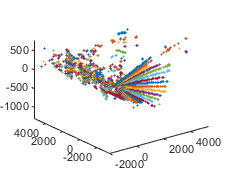

ans =   robot with properties:

        robot_cam: [1×1 webcam]
    camera_params: [1×1 cameraParameters]
          arduino: [1×1 arduino]
            lidar: [1×1 serial]
           ir_vec: ["A1"    "A2"    "A3"    "A6"]
        sonar_vec: ["A0"    "A7"]
          lsm_obj: []
              neo: []
      steer_servo: [1×1 arduinoio.Servo]
         throttle: [1×1 arduinoio.Servo]
        pan_servo: [1×1 arduinoio.Servo]
       tilt_servo: [1×1 arduinoio.Servo]


mojave.lidar_scan_3d